# FFT Examples - Noisy signal

Plot the frequency representation of the signal $x[n]$ by using the FFT function.

**Parameters** 

- 
$$x[n] = cos(2 \pi F_{0} nT_s) + k \, w_k[n]$$


- F_0 = 1 [kHz]

- F_s = 16 [kHz];

- k=[1e-8, 1e-6, 1e-4, 1e-2, 1e-1];

**FFT Function (reference: "*****help fft")***

Y = fft(X) computes the discrete Fourier transform (DFT) of X using a fast Fourier transform (FFT) algorithm

- If X is a vector, then fft(X) returns the Fourier transform of the vector.

- If X is a matrix, then fft(X) treats the columns of X as vectors and returns the Fourier transform of each column.

- If X is a multidimensional array, then fft(X) treats the values along the first array dimension whose size does not equal 1 as vectors and returns the Fourier transform of each vector.

## Clear

clc;        % 'clc' clears all the text from the Command Window
clear;      % 'clear' removes all variables from the current workspace
close all;  % 'close all' deletes all figures whose handles are not hidden.

## Parameters

len = 2^10;
F0 = 1e3;
Fs = 16e3;
Ts = 1/Fs;
k=[1e-8, 1e-6, 1e-4, 1e-2, 1e-1];

## Exercise

x = exp(1i*2*pi*F0/Fs*(0:len-1)).';
w = randn(len,1);  % (Row,Col) = (1024,1)

X = zeros(len, length(k)); % (Row,Col) = (1024,5)

for i=1:length(k)
    X(:,i) = x + k(i) * w;
end

Xf = fft(X);  % (Row,Col) = (1024,5)

Xf_abs = abs(Xf)/len;
Xf_abs_dB = mag2db(Xf_abs);

f_ax = (0:len-1)/len * Fs;
f_ax = f_ax.';

## Plot

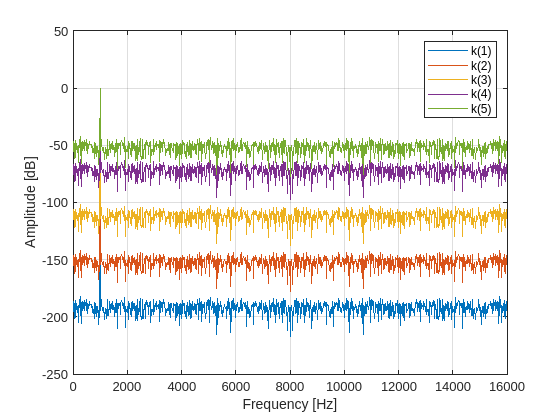

figure
plot(f_ax, Xf_abs_dB)
grid on
legend('k(1)','k(2)','k(3)','k(4)','k(5)')
xlabel('Frequency [Hz]')
ylabel('Amplitude [dB]')